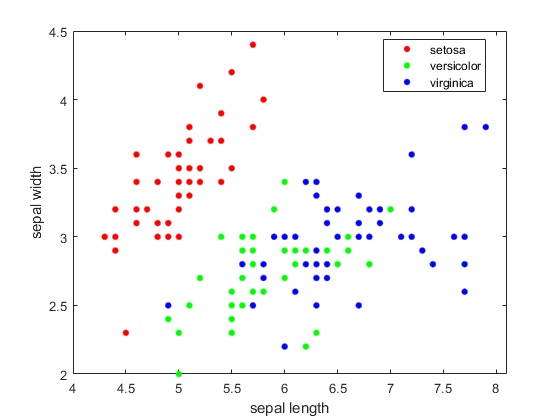

load fisheriris
x = meas(:, 1:2);
y = categorical(species);
labels = categories(y);
gscatter(x(:, 1), x(:, 2), species, 'rgb');
xlabel('sepal length')
ylabel('sepal width')

noms_cl = {'Bayes', 'LDA', 'arbre decisio', 'kNN'}

noms_cl = 1×4 cell array
    {'Bayes'}    {'LDA'}    {'arbre decisio'}    {'kNN'}


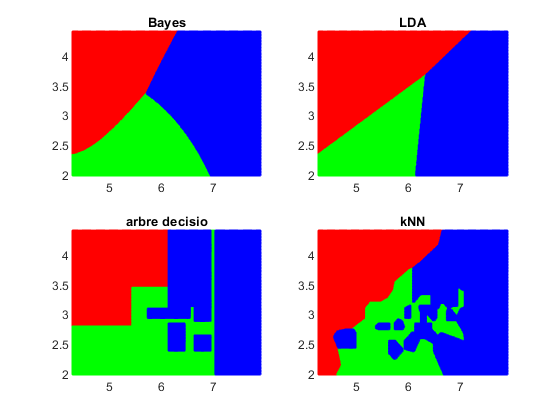

clssf{1} = fitcnb(x, y);
clssf{2} = fitcdiscr(x, y);
clssf{3} = fitctree(x, y);
clssf{4} = fitcknn(x, y);
x1rang = min(x(:, 1)):.01:max(x(:, 1));
x2rang = min(x(:, 2)):.01:max(x(:, 2));
[xx1 xx2] = meshgrid(x1rang, x2rang);
grid = [xx1(:) xx2(:)];
figure
for i = 1:4
    pred = predict(clssf{i}, grid);
    subplot(2, 2, i);
    gscatter(xx1(:), xx2(:), pred, 'rgb');
    title(noms_cl{i});
    legend off, axis tight
end


clssf{1} = fitcnb(meas, y);
clases1 = resubPredict(clssf{1});
error1 = resubLoss(clssf{1})

error1 = 0.0400

[CM, ordre] = confusionmat(y, clases1)

CM =     50     0     0
     0    47     3
     0     3    47


ordre = 3×1 categorical array
     setosa 
     versicolor 
     virginica 



clssf{2} = fitcdiscr(meas, y);
clases2 = resubPredict(clssf{2});
error2 = resubLoss(clssf{2})

error2 = 0.0200

[CM, ordre] = confusionmat(y, clases2)

CM =     50     0     0
     0    48     2
     0     1    49


ordre = 3×1 categorical array
     setosa 
     versicolor 
     virginica 



clssf{3} = fitctree(meas, y);
clases3 = resubPredict(clssf{3});
error3 = resubLoss(clssf{3})

error3 = 0.0200

[CM, ordre] = confusionmat(y, clases3)

CM =     50     0     0
     0    47     3
     0     0    50


ordre = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


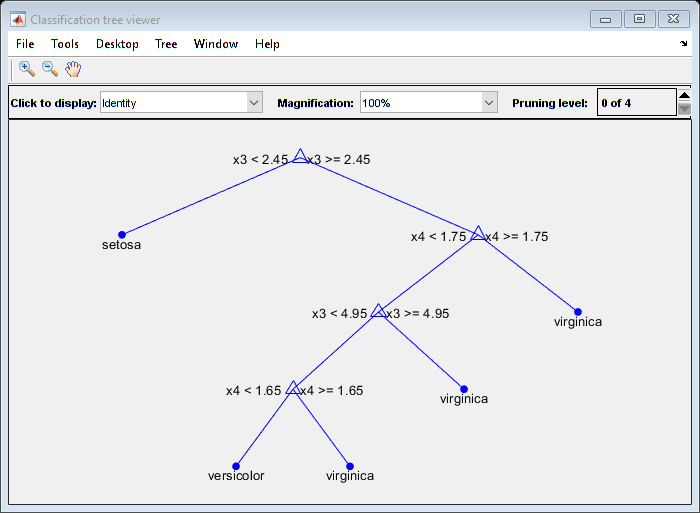

figure, view(clssf{3}, 'Mode', 'graph')


clssf{4} = fitcknn(meas, y);
clases4 = resubPredict(clssf{4});
error4 = resubLoss(clssf{4})

error4 = 0

[CM, ordre] = confusionmat(y, clases4)

CM =     50     0     0
     0    50     0
     0     0    50


ordre = 3×1 categorical array
     setosa 
     versicolor 
     virginica 
